# RANSAC- RANdomSample Consensus (Linear Least Square)

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-04

## Linear Least Square Solution: Derivation

#### Apporach 1

Reference: [http://mathworld.wolfram.com/LeastSquaresFitting.html](http://mathworld.wolfram.com/LeastSquaresFitting.html)


$$R^2(a,b) = \sum_{i=1}^{n}[y_i-(ax_i+b)]^2
$$



$$\frac{\partial R^2(a,b)}{\partial a} = -2\sum_{i=1}^{n}[y_i-(ax_i+b)] = 0
$$



$$\frac{\partial R^2(a,b)}{\partial b} = -2\sum_{i=1}^{n}[y_i-(ax_i+b)]x_i = 0$$


a and b will be 


$$a =\frac{\overline{xy} - \overline{x}\times \overline{y}}{\overline{x^2}-(\overline{x})^2}

$$



$$b =\frac{\overline{y} \times \overline{x^2}-\overline{x}\times \overline{xy}}{\overline{x^2}-(\overline{x})^2}

$$


Note that the overline ($\bar$) is used to indicate a sample mean (e.g., $\bar{x} =\frac{1}{n}\sum_i^n x_i$).

#### Apporach 2 (Pseudoinverse)

Reference: lecture slide


$$R^2(a,b) = \sum_{i=1}^{n}[y_i-(ax_i+b)]^2
$$


$R^2 \left(a,b\right)=\left\|Y-\mathrm{XB}\right\|$ where $Y=\left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_n 
\end{array}\right\rbrack$, $X=\left\lbrack \begin{array}{cc}
x_1  & 1\\
\vdots  & \vdots \\
x_n  & 1
\end{array}\right\rbrack$, $B=\left\lbrack \begin{array}{c}
a\\
b
\end{array}\right\rbrack$.


$$\left\|Y-\textrm{XB}\right\|={\left(Y-\mathrm{XB}\right)}^T \left(Y-\mathrm{XB}\right)=Y^T Y-{X\left(\mathrm{XB}\right)}^T Y+{\left(\mathrm{XB}\right)}^T \left(\mathrm{XB}\right)$$



$$\frac{{\mathrm{dR}}^2 }{\mathrm{dB}}=2X^T \mathrm{XB}-2X^T Y=0$$



$$X^T \mathrm{XB}=X^T Y$$


Solve this $\mathrm{XB}=Y$, then $B=X^{\ast } Y$.

% Pseudoinverse
% let's ten data points 
xvec = sym('x', [10 1]);
yvec = sym('y', [10 1]);

X = [xvec ones(10,1)];
Y = yvec;

Xt_X = transpose(X)*X 


$$X^{\prime } X=n\left\lbrack \begin{array}{cc}
\bar{x^2 }  & \bar{x} \\
\bar{x}  & 1
\end{array}\right\rbrack$$
 

inv_Xt_X = inv(Xt_X)

${\left\lbrack X^{\prime } X\right\rbrack }^{-1} =\frac{n}{\sigma }\left\lbrack \begin{array}{cc}
-1 & \bar{x} \\
\bar{x}  & -\bar{x^2 } 
\end{array}\right\rbrack$where $\sigma ={\left\lbrack \sum_i^n x_i \right\rbrack }^2 -n^2 \bar{x^2 } ={n^2 \left\lbrack \bar{x} \right\rbrack }^2 -n^2 \bar{x^2 }$

pinv_X = inv_Xt_X*transpose(X)


$${\left\lbrack X^{\prime } X\right\rbrack }^{-1} X^{\prime } =\frac{n}{\sigma }\left\lbrack \begin{array}{ccc}
\bar{x} -x_1  & \cdots  & \bar{x} -x_n \\
x_1 \bar{x} -\bar{x^2 }  & \cdots  & x_n \bar{x} -\bar{x^2 } 
\end{array}\right\rbrack$$


pinv_X_Y = pinv_X*Y


$${\left\lbrack X^{\prime } X\right\rbrack }^{-1} X^{\prime } Y=\frac{n}{\sigma }\left\lbrack \begin{array}{c}
\bar{x} \sum_i^n y_i -\sum_i^n {x_i y}_i \\
\bar{x} \sum_i^n x_i y_i -x^2 \sum_i^n y_i 
\end{array}\right\rbrack =\frac{1}{{\left(\bar{x} \right)}^2 -\bar{x^2 } }\left\lbrack \begin{array}{c}
\bar{x} \times \bar{y} -\bar{\textrm{xy}} \\
\bar{x} \times \bar{\textrm{xy}} -\bar{x^2 \;} \times \bar{y} 
\end{array}\right\rbrack$$


**Q: Please check if above two solutions are same. **

### Linear Least Square Solution:Simulation

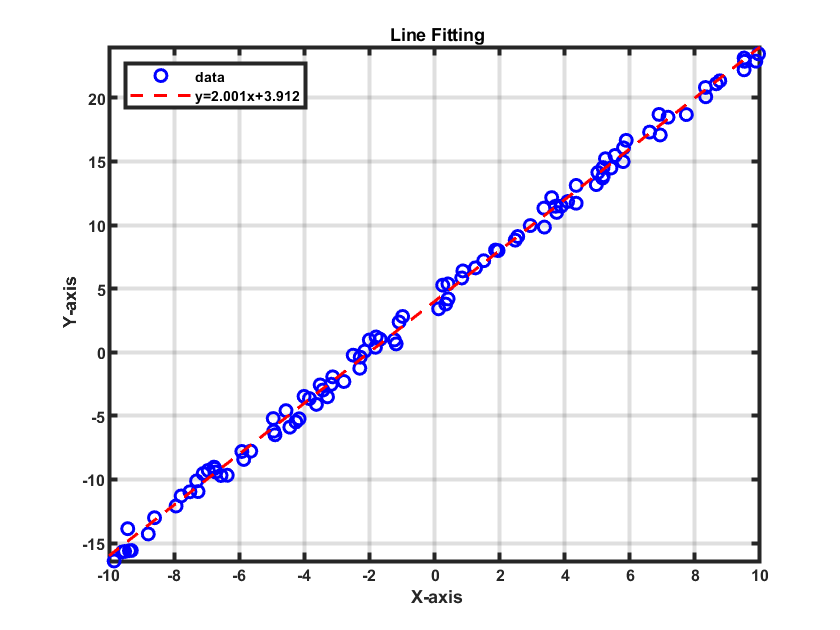

% line fitting (only measurement error)
num_pt = 100;

% line equation y = mx + b;
m = 2;
b = 4;

% x-axis range
xrange = [-10 10];
x = rand(num_pt,1)*(xrange(2)-xrange(1))+xrange(1);

y_true = m*x+b;
x_meas = x; 
y_meas = y_true + (rand([num_pt 1])*2-1);

Xmat = [x_meas ones(num_pt,1)];
Ymat = y_meas;
fparam = pinv(Xmat)*Ymat;

figure(1)
plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);
line(xrange,m*xrange + b, 'Color', 'r', 'linewidth',  1.5, 'LineStyle', '--');
legend({'data',strcat('y=',sprintf('%3.3f',fparam(1)),'x+',sprintf('%3.3f',fparam(2)))},'location','northwest')
axis tight;grid on; hold off
title('\bf Line Fitting');
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

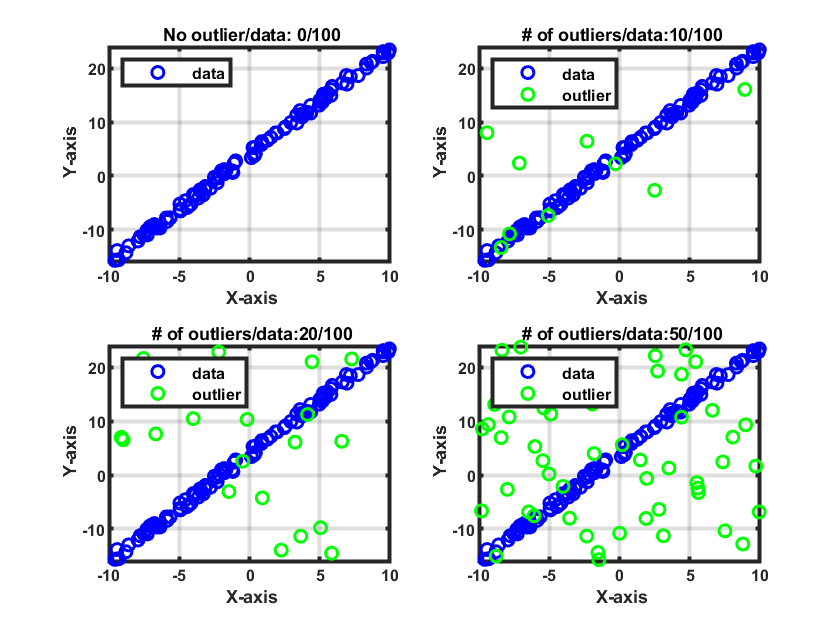



% line fitting (measurement error + outlier)

% outlier ratios (0%, 10%, 20%, 50%)
out_ratio = [0 0.1 0.2 0.5];
x_out = cell(4,1);
y_out = cell(4,1);
yrange = m*xrange+b;

fparam_set = zeros(2,numel(out_ratio));
for ii=1:numel(out_ratio)
    x_out{ii} = rand(num_pt*out_ratio(ii),1)*(xrange(2)-xrange(1))+xrange(1);
    y_out{ii} = rand(num_pt*out_ratio(ii),1)*(yrange(2)-yrange(1))+yrange(1);
    
    num_pt_new = num_pt + numel(x_out{ii});
    
    Xmat = [[x_meas;x_out{ii}] ones(num_pt_new,1)];
    Ymat = [y_meas;y_out{ii}];
    fparam_set(:, ii) = pinv(Xmat)*Ymat;
end

figure(2)
subplot(221); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
legend('data','location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf No outlier/data: 0/', sprintf('%d',num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(222); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
plot(x_out{2}, y_out{2}, 'og', 'linewidth', 1.5);
legend('data','outlier','location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(2), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(223); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
plot(x_out{3}, y_out{3}, 'og', 'linewidth', 1.5);
legend('data','outlier','location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(3), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(224); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
plot(x_out{4}, y_out{4}, 'og', 'linewidth', 1.5);
legend('data','outlier','location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(4), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

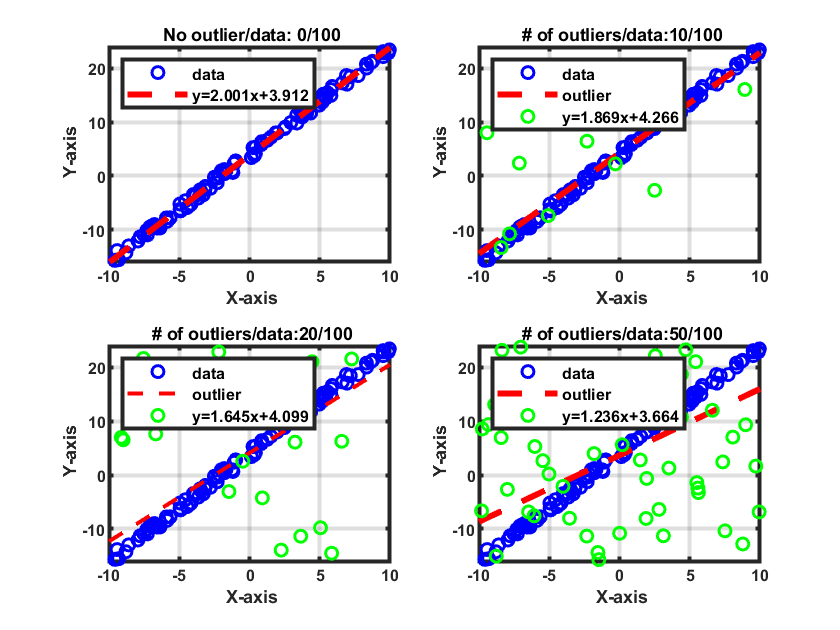


figure(3)
subplot(221); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
line(xrange,fparam_set(1,1)*xrange + fparam_set(2,1), 'Color', 'r', 'linewidth',  3, 'LineStyle', '--');
legend({'data',strcat('y=',sprintf('%3.3f',fparam_set(1,1)),'x+',sprintf('%3.3f',fparam_set(2,1)))},'location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf No outlier/data: 0/', sprintf('%d',num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(222); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
line(xrange,fparam_set(1,2)*xrange + fparam_set(2,2), 'Color', 'r', 'linewidth',  3, 'LineStyle', '--');
plot(x_out{2}, y_out{2}, 'og', 'linewidth', 1.5);
legend({'data','outlier',strcat('y=',sprintf('%3.3f',fparam_set(1,2)),'x+',sprintf('%3.3f',fparam_set(2,2)))},'location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(2), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(223); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
line(xrange,fparam_set(1,3)*xrange + fparam_set(2,3), 'Color', 'r', 'linewidth',  2, 'LineStyle', '--');
plot(x_out{3}, y_out{3}, 'og', 'linewidth', 1.5);
legend({'data','outlier',strcat('y=',sprintf('%3.3f',fparam_set(1,3)),'x+',sprintf('%3.3f',fparam_set(2,3)))},'location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(3), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')

subplot(224); plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
line(xrange,fparam_set(1,4)*xrange + fparam_set(2,4), 'Color', 'r', 'linewidth',  3, 'LineStyle', '--');
plot(x_out{4}, y_out{4}, 'og', 'linewidth', 1.5);
legend({'data','outlier',strcat('y=',sprintf('%3.3f',fparam_set(1,4)),'x+',sprintf('%3.3f',fparam_set(2,4)))},'location','northwest','FontSize',8)
axis tight;grid on; hold off
title(strcat('\bf # of outliers/data: ', sprintf('%d/%d',num_pt*out_ratio(4), num_pt)));
xlabel('\bf X-axis');xlim(xrange);
ylabel('\bf Y-axis');ylim(yrange);
set(gca,'FontSize',8,'linewidth',2,'fontweight','bold')


% figures below for slide preparation

% figure(4)
% plot(x_meas, y_meas, 'ob', 'linewidth', 1.5);hold on;
% plot(x_out{4}, y_out{4}, 'or', 'linewidth', 1.5);
% legend({'data','outlier'},'location','northwest','FontSize',10)
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',12,'linewidth',2,'fontweight','bold')
% 
% figure(5)
% plot([x_meas;x_out{4}], [y_meas;y_out{4}], 'ob', 'linewidth', 1.5);hold on;
% legend('data','location','northwest','FontSize',10)
% axis tight;grid on; hold off
% xlabel('\bf X-axis');xlim(xrange);
% ylabel('\bf Y-axis');ylim(yrange);
% set(gca,'FontSize',12,'linewidth',2,'fontweight','bold')